This is a separate livescipt for estimating marker mediator effect during the pain delivery pahse between visual deactivation and rating. 

# NPS

Mediation analysis

Observations:  17, Replications:  17
Predictor (X): Putact, Outcome (Y): Rating: Mediator (M): NPS

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: Yes
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 001
Bootstrapping:  Min p-value is 0.206200. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
002
Bootstrapping:  Min p-value is 0.003800. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
003
Bootstrapping:  Min p-value is 0.298800. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
004
Bootstrapping:  Min p-value is 0.225000. Adding   0 samples
 Done in   0 (s

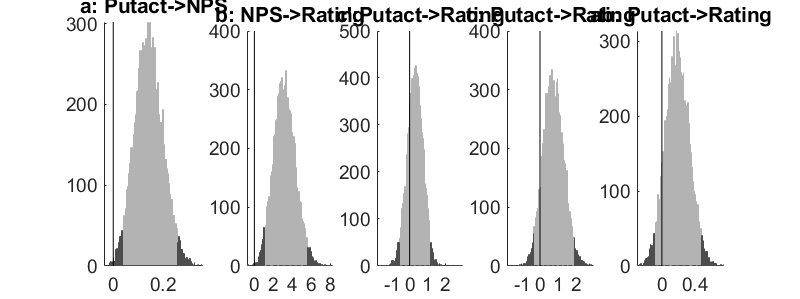

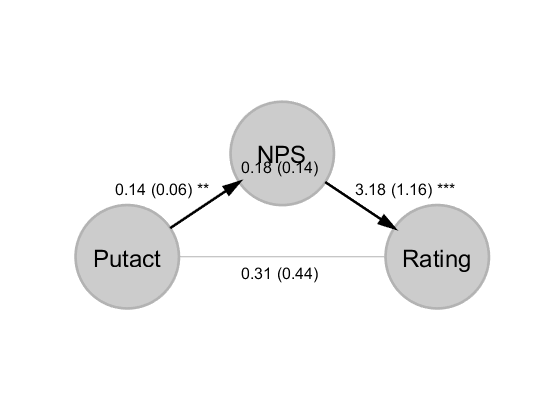

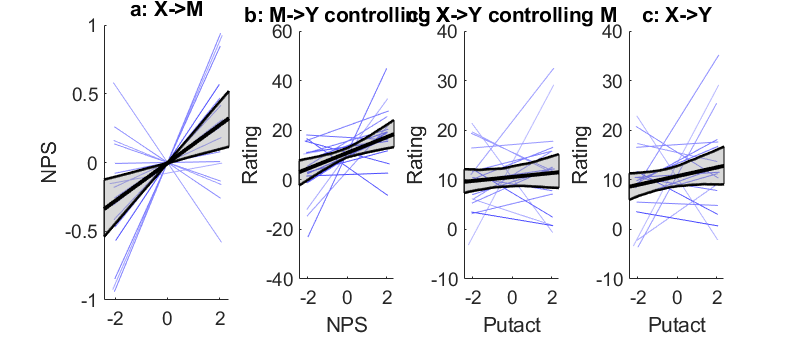

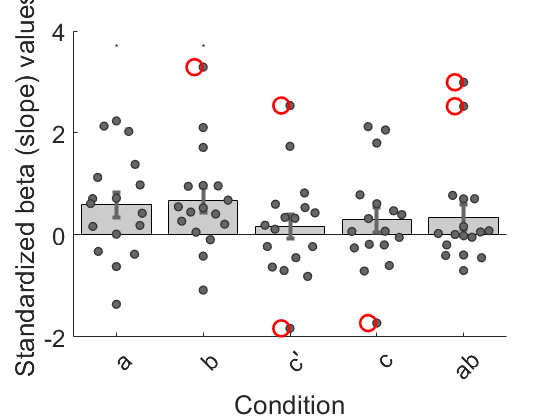

No second-level covariates; omitting 2nd level scatterplots.


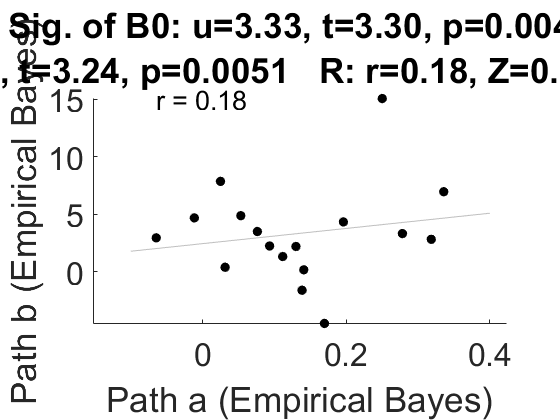


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	0.14	3.18	0.31	0.74	0.18	
STE	0.06	1.16	0.44	0.57	0.14	
t (~N)	2.57	2.74	0.70	1.30	1.28	
Z	3.04	3.50	0.68	1.39	1.34	
p	0.0024	0.0005	0.4974	0.1658	0.1817	

________________________________________
Total time:  17 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.NPS";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.visualdeactivation{k,1}(:);
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths_nps, stats_nps] = mediation(X, Y,M, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootstrapfirst','bootsamples', 10000, 'hierarchical', ...
    'names', {'Putact' 'Rating' 'NPS'});

# SIIPS

Mediation analysis

Observations:  17, Replications:  17
Predictor (X): Putact, Outcome (Y): Rating: Mediator (M): SIIPS

Covariates: No

Multi-level analysis.
Options:
	Multilevel weights: Yes
	Plots: Yes
	Bootstrap: Yes
	Sign perm: No
	Robust: No
	Logistic(Y): No
	Bootstrap 1st level: Yes
	Bootstrap or sign perm samples: 10000

Getting estimates for replications: 001
Bootstrapping:  Min p-value is 0.018000. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
002
Bootstrapping:  Min p-value is 0.015800. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
003
Bootstrapping:  Min p-value is 0.332200. Adding   0 samples
 Done in   0 (s) 
Additions 10/28/19 by Tor Wager to add output to within-ss stats need checking to avoid code conflicts
004
Bootstrapping:  Min p-value is 0.340600. Adding   0 samples
 Done in   0 

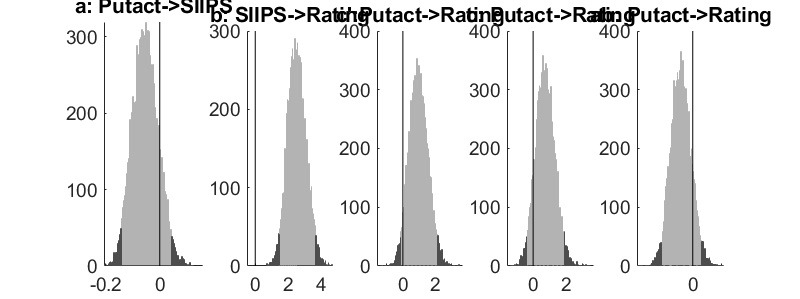

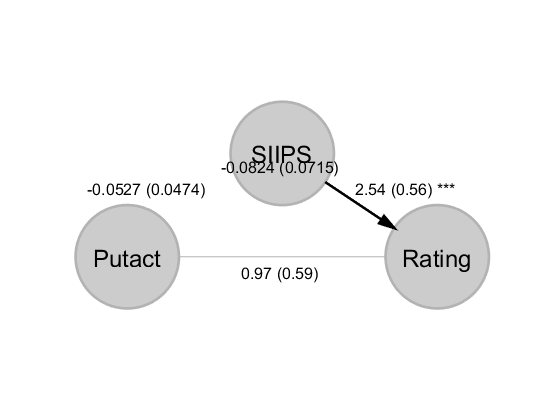

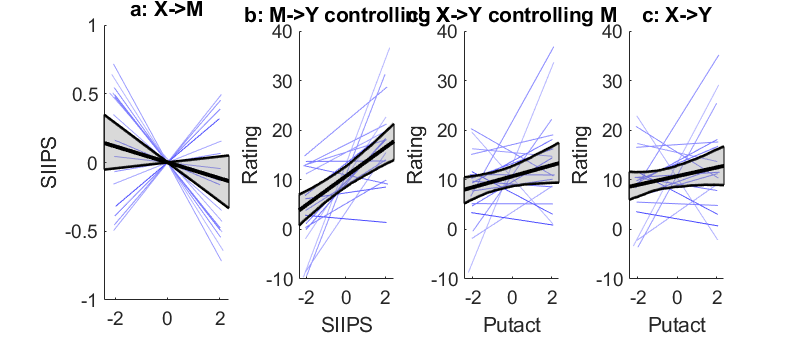

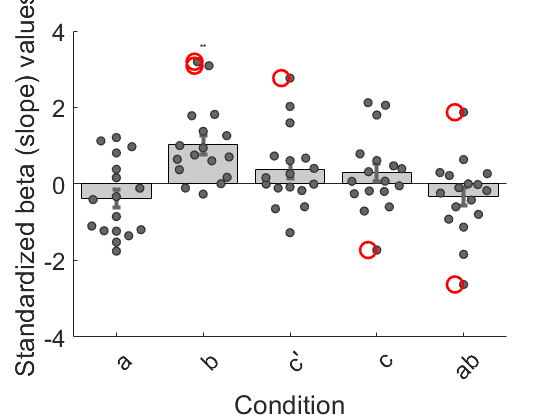

No second-level covariates; omitting 2nd level scatterplots.


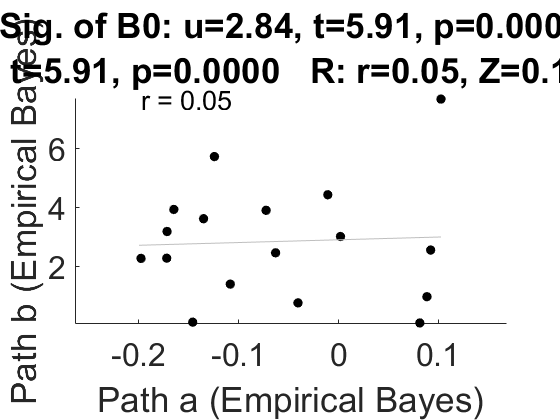


________________________________________
Average p-value tolerance (average max alpha): 0.0060

Multi-level model
	a	b	c'	c	ab	
Coeff	-0.05	2.54	0.97	0.74	-0.08	
STE	0.05	0.56	0.59	0.58	0.07	
t (~N)	-1.11	4.52	1.65	1.27	-1.15	
Z	-1.16	4.24	1.83	1.38	-1.21	
p	0.2460	0.0000	0.0673	0.1680	0.2251	

________________________________________
Total time:  16 s



%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.siips";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.visualdeactivation{k,1}(:);
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths_siips, stats_siips] = mediation(X, Y,M, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootstrapfirst','bootsamples', 10000, 'hierarchical', ...
    'names', {'Putact' 'Rating' 'SIIPS' });

# Conclusion of the findings above:

Nonce of the marker mediates the correlation between visual deactivation and rating difference.

% %saving the outputs
% stats=stats_siips;
% pathNames = stats.names';
% 
% T = array2table([stats.mean; stats.ste; stats.z; stats.p], ...
%     'VariableNames', {'a','b','cp','c','ab'}, ...
%     'RowNames', {'Coeff','STE','Z','p'});
% 
% disp(T)

                a           b             cp            c            ab    
             _______    __________    __________    __________    _________

    Coeff     104.79     0.0019643        6.1281        6.9901    -0.037874
    STE       142.94    0.00040227        1.4806        1.8625      0.21379
    Z        0.85792        4.1222        4.0665        4.3243     0.060949
    p        0.39093    3.7522e-05    4.7732e-05    1.5302e-05       0.9514



% 
% % Save
% pathtosave = 'C:\Users\lenov\Documents\PICO\C_calculations\mygithubproject\anticipation_analysis\F_additionalanalysis\mediationanalysis\results'

pathtosave = 'C:\Users\lenov\Documents\PICO\C_calculations\mygithubproject\anticipation_analysis\F_additionalanalysis\mediationanalysis\results'

% writetable(T, fullfile(pathtosave,'mediation_results_siips.csv'));
% save(fullfile(pathtosave,'mediation_results_siips.mat'), 'paths', 'stats', 'T');


%runmultilevel mediation, in which groups are handled in the model
% single level mediation (ignoringthe group variable) can cause inflated
% false positives,...
% one has to load the mother of tables to get the data what is used here:
moderatorpath= "pain_placebo_minus_control.NPS";
ratingpath = "GIV_stats_rating101.delta";
covvars1="pain_placebo_minus_control.male";
covvars2="pain_placebo_minus_control.age";
K = height(df);  % number of groups/studies

X = cell(K,1);
M = cell(K,1);
cov = cell(K,1);
Y = cell(K,1);

for k = 1:K
    if ~isempty(df.putamensctivation{k,1}(:))
        X{k} = -df.putamensctivation{k,1}(:);
        X{k} = (X{k} - mean(X{k},'omitnan')) ./ std(X{k},'omitnan');   % z-score
        M{k} = extractVectorFromPath(df, moderatorpath, k, true);
        M{k} = (M{k} - mean(M{k},'omitnan')) ./ std(M{k},'omitnan');   % z-score
        cov{k} = [extractVectorFromPath(df, covvars1, k, false) extractVectorFromPath(df, covvars2, k, false)];
        Y{k} = extractVectorFromPath(df, ratingpath, k, true);           % reverse rating if needed
    
        % (optional) remove rows with NaN in any variable
        valid = isfinite(X{k}) & isfinite(M{k}) & isfinite(Y{k}); %we assume that covariates (age anare always provided
        X{k} = X{k}(valid);
        M{k} = M{k}(valid);
        cov{k} = cov{k}(valid,:);
        Y{k} = Y{k}(valid);
    end
end

% Remove empty groups
empty = cellfun(@isempty, X) | cellfun(@isempty, M) | cellfun(@isempty, Y) | cellfun(@isempty, cov);
X(empty) = []; M(empty) = []; Y(empty) = []; cov(empty) = [];
%'covs',cov, - note that adding this to the mediation analysis might end up in issues as there is no covariance in some of the studies (average value is introduced and not the indiviudalv alues)
[paths, stats] = mediation(X, M, Y, ...
    'boot', 'verbose','plots',... %'plots', 
    'boottop','bootsamples', 10000, 'hierarchical');

function v = extractVectorFromPath(df, valuePath, rowIdx, doReverse)
    % Extract a numeric vector from df at rowIdx following "var" or "var.field".
    valuePath = string(valuePath);
    parts = split(valuePath,".");
    baseVar = parts(1);
    subField = "";
    if numel(parts) > 1
        subField = parts(2);
    end
    
    v = [];
    
    obj = df.(baseVar)(rowIdx);
    if iscell(obj), obj = obj{1}; end
    if isempty(obj), return; end
    
    if subField ~= ""
        if istable(obj)
            if ~ismember(subField, string(obj.Properties.VariableNames)), return; end
            v = obj.(subField);
        elseif isstruct(obj)
            if ~isfield(obj, subField), return; end
            v = obj.(subField);
        else
            return
        end
    else
        v = obj;
    end
    
    if isempty(v), v = []; return; end
    v = v(:);
    
    if doReverse
        v = -v;
    end
end